ans =     1.0000    3.8889
    2.0000    4.5556
    3.0000    5.2222
    4.0000    5.8889
    5.0000    6.5556


ans = 300

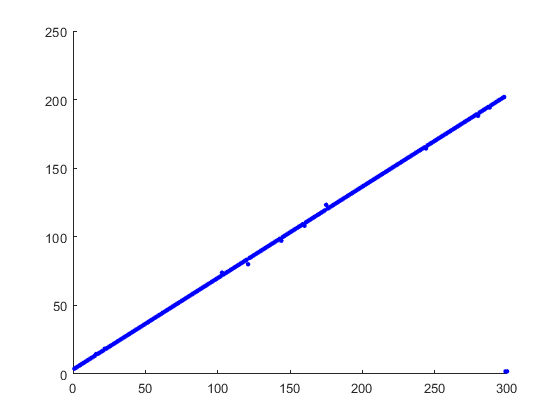

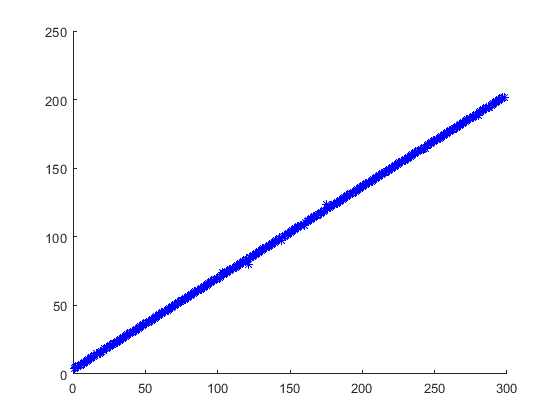

x =      1     1
     1     2
     1     3
     1     4
     1     5
     1     6
     1     7
     1     8
     1     9
     1    10


p =     3.2378
    0.6665


y_pred =   169.8513
  170.5177
  171.1842
  171.8506
  172.5171
  173.1835
  173.8500
  174.5164
  175.1829
  175.8493


Mean Square Error(MSE): 0.07
R_square value is: 0.9992 %

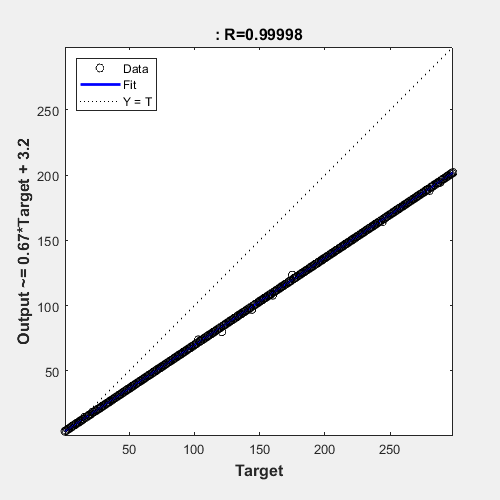

%Loading the Dataset:
cd 'D:\'

df = load('Linear_Regression.csv');
df(1:5,1:2)
x = df(:,1); % Feature (Independent variable)
y = df(:,2); % Dependent variables 
length(x)
scatter(x,y,12,'filled','blue')
% There are some Outliers at the end of the regression line.
x = x(1:298,1);
y = y(1:298,1);
scatter(x,y,'*','blue') 
% Including the Parameter X0:
temp = ones(298,1);
x = [temp x]
%Train-test Split:
x_train = x(1:250,:);
x_test = x(250:298,:);
y_train = y(1:250,1);
y_test = y(250:298,1);

% Normal Equation:
p = (x_train' * x_train) \ x_train' *y_train      % inv(A)*b == A\b.
%Prediction:
y_pred = x_test * p
% Metrics or Parameter testing:
% Mean Squared Error(MSE):
t = y_test - y_pred;
t = t .^2;
MSE = sum(t)/length(t);

% R_square value: 
y_m = mean(y_test);
y_m1 = ones(49,1)*y_m;
r1 = (y_test - y_m);
r1= r1.^2;
r2 = (y_test - y_pred);
r2=r2.^2;
r2_acc = 1- sum(r2)/sum(r1);
fprintf('Mean Square Error(MSE): %.2f\nR_square value is: %.4f %%',MSE,r2_acc*100.0);
%Matrix Dimension should be same:
x = x(:,2);
plotregression(x,y)
